# **Cerca fdt del Meca500 da risposta indiciale**

#### inizializzazione dell'ambiente

clear
close all
clc

lettura file csv

% Specify the file path
file_path = 'control_10/position_response';

% Use readmatrix to read the two-column CSV file
data = readmatrix(file_path);

% Extract X and Y values from the columns
time_values = data(:, 1);
pos_resp_values = data(:, 2);

% Extract only the first 500 value (indicial response)
time_values = time_values(1:500);
pos_resp_values = pos_resp_values(1:500);

% Origin reference system
% control_10 -> 130, control_20 -> 100
move_origin = 130;

pos_resp_values = pos_resp_values - move_origin;

#### Definizione della funzione di trasferimento del processo

Tau = 0.07;
T = 0.12;
mu = 1;

G = tf(mu, [T 1 0])

G =
 
        
       1
        
  -----------
             
  0.12 s^2   
             
          + s
             
 
Continuous-time transfer function.



G.ioDelay = Tau

G =
 
                       
                      1
                       
  exp(-0.07*s) * -----------
                            
                 0.12 s^2   
                            
                         + s
                            
 
Continuous-time transfer function.



#### Risposta al gradino


%step size has to be setted by user mulitplying risp_indiciale
%ps: control_10 -> stepsize = 10, control_20 -> stepsize = 20
step_size = 10;

%compute
[risp_indiciale, tempo] = step(G);
risp_indiciale = risp_indiciale * step_size

risp_indiciale =          0
         0
         0
         0
         0
         0
         0
    0.0022
    0.0134
    0.0334



%compare on the same time
tempo = tempo(1:258);
risp_indiciale = risp_indiciale(1:258);


Confronto sullo stesso grafico Position_Response e Risposta_Gradino

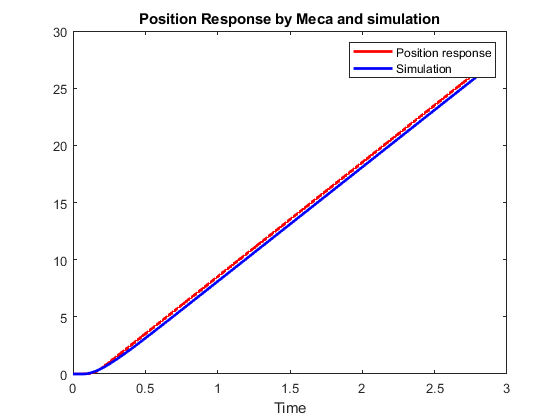

% Plot the first graph
plot(time_values, pos_resp_values, 'r-', 'LineWidth', 2); % Red line

hold on;

% Plot the second graph
plot(tempo, risp_indiciale, 'b-', 'LineWidth', 2); % Blue line

% Add labels and a legend
xlabel('Time');
ylabel('');
title('Position Response by Meca and simulation');
legend('Position response', 'Simulation');

% Turn off the hold to allow for new plots
hold off;

% Save the plot as a PNG file (you can choose other formats like JPEG, PDF, etc.)
%saveas(gcf, 'simulation_tf/simulation10.png');